# CME192 Assignment 2, Part 3: Image Processing

In this section, we are reviewing basic image processing techniques reviewed in Lecture 07 on synthetic toy image data. 

## Part A: Setup + data loading + first look

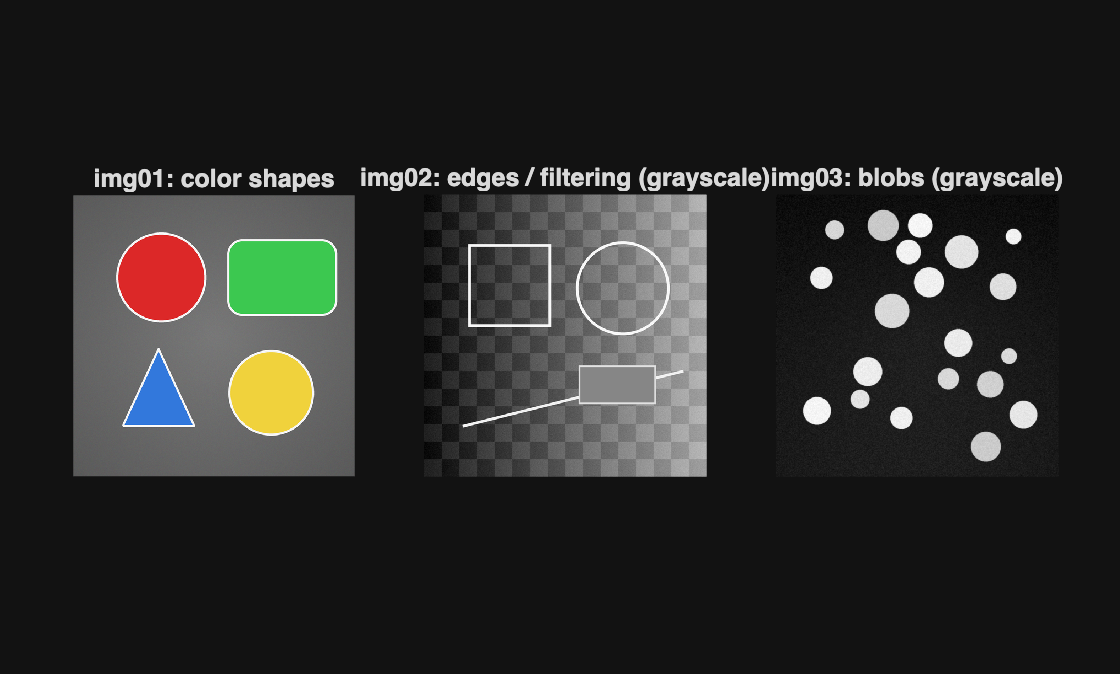

clear; close all; clc;

zipFile = "MatlabIPBasicsDataset.zip";
dataDir = fullfile(pwd,"MatlabIPBasicsDataset");

if ~exist(dataDir,"dir")
    if exist(zipFile,"file")
        unzip(zipFile, pwd);
    else
        error("Missing %s. Put the zip file in this folder and re-run.", zipFile);
    end
end

img1Name = "img01_color_shapes.png";
img2Name = "img02_edges_filtering.png";
img3Name = "img03_blobs_segmentation.png";

I1 = imread(fullfile(dataDir, img1Name));
I2 = imread(fullfile(dataDir, img2Name));
I3 = imread(fullfile(dataDir, img3Name));

figure("Name","Step 0: First look");
tiledlayout(1,3,"Padding","compact","TileSpacing","compact");

nexttile; imshow(I1); title("img01: color shapes");
nexttile; imshow(I2,[]); title("img02: edges / filtering (grayscale)");
nexttile; imshow(I3,[]); title("img03: blobs (grayscale)");

## Part B: Working with color channels + simple color filter (6 pts)

Goal: 1) Split the RGB image into R, G, B channels (multi-band intuition). 2) Visualize each channel. 3) Make a very simple "color filter": keep ONLY red-ish pixels.

Choose from (all appear in Lecture_07_Astronomy.mlx): imsplit, imhist, bwareaopen, montage, tiledlayout, nexttile, imshow

% TODO: Split the RGB image into R, G, B channels (multi-band intuition). 
% Follow the example given in Lecture_07_Astronomy.mlx: "5) Grayscale and
% Color Images (multi-band intuition)"
[R1,G1,B1] = ___________________________;
figure("Name","Step 1A: RGB channels");
tiledlayout(2,2,"Padding","compact","TileSpacing","compact");
nexttile; imshow(I1); title("RGB");
nexttile; imshow(R1,[]); title("R channel");
nexttile; imshow(G1,[]); title("G channel");
nexttile; imshow(B1,[]); title("B channel");
% What to expect:
% - R channel bright where red circle is
% - G channel bright where green rectangle is
% - B channel bright where blue triangle is

% Now, let's apply a simple color "filter" (mask) for red-ish pixels.
% NOTE: This is intentionally simple. The point is to practice channel logic.
redMask = (R1 > 180) & (G1 < 140) & (B1 < 140);
% TODO: Clean mask by removing small speckles. Recall the example from
% Lecture_07_Astronomy.mlx: "10) Working with binary images"
% The example from lecture used: BW = bwareaopen(BW, 30);
redMask = _____________(redMask, 50);
I1_redOnly = I1;
I1_redOnly(repmat(~redMask,[1 1 3])) = 0;
figure("Name","Step 1C: Simple color filter");
tiledlayout(1,3,"Padding","compact","TileSpacing","compact");
nexttile; imshow(I1); title("Original (RGB)");
nexttile; imshow(redMask); title("Red mask (binary)");
nexttile; imshow(I1_redOnly); title("Red-only image");
% What to expect:
% - The red mask should mostly capture the red circle
% - The red-only image should show only the red circle (other regions black)

## Part C: Rotate + binarize + visualize (6 pts)

Goal: 1) Rotate the image by a small angle. 2) Binarize the rotated image (global threshold). 3) Visualize.

Choose from (all appear in Lecture_07_Astronomy.mlx): imrotate, imshowpair, imbinarize, tiledlayout, imshow

% TODO: Rotate the image. Recall the example in Lecture_07_Astronomy.mlx: "6)
% Rotation / Registration and Difference Imaging"
I2_rot = _____________(I2, 5, "bicubic", "crop");
figure("Name","Step 2A: Rotation visualization");
imshowpair(I2, I2_rot, "montage");
title("Original (left) vs Rotated (right)");

% TODO: Binarize the image. Follow the example from
% Lecture_07_Astronomy.mlx:
% "9) Thresholding as a first-pass 'source detection'"
BW2 = _______________(I2_rot); % global (Otsu)
figure("Name","Step 2B: Rotation + binarize");
tiledlayout(1,3,"Padding","compact","TileSpacing","compact");
nexttile; imshow(I2,[]); title("Original");
nexttile; imshow(I2_rot,[]); title("Rotated");
nexttile; imshow(BW2); title("Binarized (global)");
% What to expect:
% - Rotated image looks like img02, slightly turned
% - Binarized image separates bright outlines from darker background (roughly)

## Part D: Segment blobs + clean + label + count & measure (6 pts)

Goal: 1) Segment blobs using a global threshold. 2) Clean the mask. 3) Label + count objects, then measure Area + Centroid. 4) Visualize labels and overlay centroids.

Choose from (all appear in Lecture_07_Astronomy.mlx): imbinarize, bwareaopen

% TODO: Segment with a global threshold following Lecture_07_Astronomy.mlx: 
% "9) Thresholding as a first-pass "source detection"
BW3 = _____________(I3);

% TODO: Remove small objects following Lecture_07_Astronomy.mlx: 
% "10) Working with binary images"
BW3 = _______________(BW3, 30);

BW3 = imfill(BW3, "holes");

cc = bwconncomp(BW3);
numObjects = cc.NumObjects;
stats = regionprops(cc, "Area", "Centroid");
areas = [stats.Area]';
centroids = cat(1, stats.Centroid);

% Visualizations
L = labelmatrix(cc);
RGB = label2rgb(L, "jet", "k", "shuffle");

figure("Name","Step 3A: Segmentation summary");
tiledlayout(1,3,"Padding","compact","TileSpacing","compact");
nexttile; imshow(I3,[]); title("Original (img03)");
nexttile; imshow(BW3); title("Clean binary mask");
nexttile; imshow(RGB); title("Labels (label2rgb)");

figure("Name","Step 3B: Overlay (boundaries + centroids)");
imshow(I3,[]); hold on;

B = bwboundaries(BW3);
for k = 1:numel(B)
    boundary = B{k};
    plot(boundary(:,2), boundary(:,1), "y", "LineWidth", 1);
end

plot(centroids(:,1), centroids(:,2), "r+", "LineWidth", 1.5);
title("Boundaries + centroids overlaid on original");
hold off;

T = table((1:numObjects)', areas, centroids(:,1), centroids(:,2), ...
    VariableNames = ["ObjectID","Area","CentroidX","CentroidY"]);
disp(T(1:min(10,height(T)),:));

expectedCount = 20;
fprintf("Step 3 check: expected %d blobs, found %d blobs.\n", expectedCount, numObjects);

if numObjects == expectedCount
    disp("Count matches expected value (20).");
else
    warning("Count mismatch: expected %d but found %d. Try adjusting imbinarize / bwareaopen.", expectedCount, numObjects);
end
% What to expect:
% - numObjects should be 20
% - label image shows 20 labeled circles
% - centroid plot shows one marker near the center of each blob